Te = 0.3;
K = 1;

num = [K];
den = [1 1 0];

[numd, dend] = c2dm(num, den, Te, 'foh');

G0 = tf(numd, dend);
G1 = feedback(G0,1)


G1 =
 
  0.01394 s^2 + 0.05182 s + 0.012
  -------------------------------
   1.014 s^2 - 1.689 s + 0.7528
 
Continuous-time transfer function.


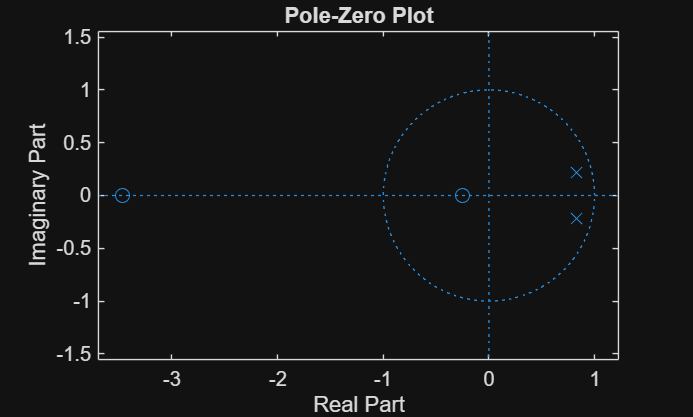


zplane(G1.Numerator{1}, G1.Denominator{1})